# Esercizio Break Even Point grafico

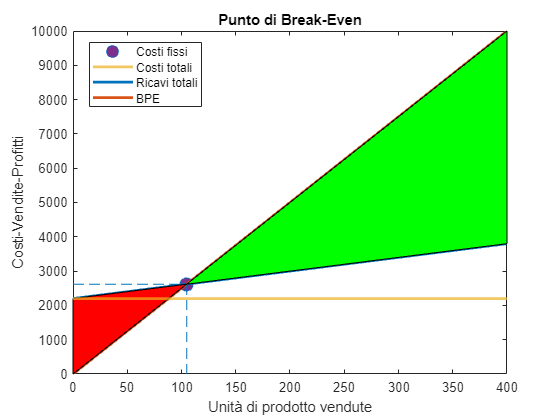

% creare un grafico con gli slider per il break even point come quello
% raffigurato nel punto 5 degli esercizi extra

clear all;
close all;
clc;


%inizio col mettere gli slider come richiesto

Cx=4;
Px=25;
FC=2200;

%trovo il BEP in modo numerico
x= 400;
BEP= FC/(Px-Cx);
Cequi= FC+(Cx*BEP);
Ctot= FC+(Cx*x);
Rtot= Px*x;
Area= true;
PBE= true;

%questa if condition mostra l'errore nel caso il BEP fosse maggiore di 400
%o minore di 0

% mettere "|| BEP<0" non è necessario in quanto è impossibile che esso sia
% minore di 0, allungherebbe solo il codice senza motivo

if BEP>400 
    error(['Errore, il punto di Break Even non è definito tra ' num2str(0) ' e ' num2str(400)])
end

figure
%ho impostato markersize=10 anzichè 100, credo si tratti di un errore di trascrizione
plot(BEP,Cequi, 'o', 'MarkerFaceColor', [0.4940 0.1840 0.5560], 'MarkerSize',10 );
xlim([0,400])
xlabel("Unità di prodotto vendute")
ylabel("Costi-Vendite-Profitti")
title('Punto di Break-Even')
yline(FC, 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250]) %questa linea rappresenta i costi fissi (Fixed Costs= FC)
line([0,400],[FC,Ctot], 'LineWidth', 2, 'Color', [0 0.4470 0.7410]) %questa linea aggiunge i costi totali C(x)+FC
line([0,400],[0,Rtot], 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980])  %questa linea aggiunge al grafico i ricavi tot P*x

%aggiungo la legenda e tolgo l'auto update in quanto mi andrebbe ad
%aggiungere labels che non mi interessano
lgd= legend('Costi fissi', 'Costi totali', 'Ricavi totali', 'BPE',Location='best');
lgd.AutoUpdate="off";

%if condition per mostrare BPE, il primo mi serve per vedere la legenda
%senza bpe

if PBE == true
    %le due prossime linee tratteggiate mostrano le coordinate del punto di
    %Break Even
    line([BEP,BEP], [0, Cequi] , LineStyle="--")
    line([0,BEP], [Cequi,Cequi], LineStyle="--")
end

%if condition per mostrare le aree colorate nel grafico
if Area == true
    hold on
    Xl= [0 0 BEP];
    Yl= [0 FC, Cequi];
    fill(Xl,Yl, 'r' )
    Xu= [BEP, 400, 400];
    Yu= [Cequi, Ctot, Rtot];
    fill(Xu, Yu, 'g')
    hold off
end

%risoluzione del sistema di equazioni con implementazione matriciale

A= [Cx, -1; Px, -1];
b= [-FC; 0];

BEPeq= A\b;
assert(abs(BEPeq(1)-BEP)<1e-12, 'le due implementazioni di BEP differiscono')
disp (['Il punto di Break-Even è di ' num2str(BEPeq(1)) ' unità quando il costo totale è ' num2str(BEPeq(2))])

Il punto di Break-Even è di 104.7619 unità quando il costo totale è 2619.0476
